# MARTEC Machine Learning forecasting

clear
opts = delimitedTextImportOptions("NumVariables", 18, "Encoding", "UTF-8");

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Ciudad", "Poblacion", "Semana", "Max_Campus", "WBE_Dato", "x_EdMuestreados", "x_EdPositivos", "Retail_Recreation", "Grocery_Pharmacy", "Parks", "Public_transport", "Workplaces", "Residential", "AVG_Mobility", "Casos", "Ola", "Pred_1_S", "Pred_2_S"];
opts.VariableTypes = ["categorical", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "Ciudad", "EmptyFieldRule", "auto");
opts = setvaropts(opts, ["Poblacion", "x_EdPositivos"], "TrimNonNumeric", true);
opts = setvaropts(opts, ["Poblacion", "x_EdPositivos"], "ThousandsSeparator", ",");

% Import the data
MTY_CDMX_Combinado = readtable("/MATLAB Drive/Modelos predictivos/MTY_CDMX_Combinado.csv", opts)

MTY_CDMX_Combinado = 148x18 table
    Ciudad    Poblacion     Semana    Max_Campus     WBE_Dato     x_EdMuestreados    x_EdPositivos    Retail_Recreation    Grocery_Pharmacy     Parks     Public_transport    Workplaces    Residential    AVG_Mobility    Casos     Ola    Pred_1_S    Pred_2_S
    ______    __________    ______    __________    __________    _______________    _____________    _________________    ________________    _______    ________________    __________    ___

clear opts

Pob=MTY_CDMX_Combinado.Poblacion;
Casos=(MTY_CDMX_Combinado.Casos./Pob)*100000;
MTY_CDMX_Combinado.Casos=Casos

MTY_CDMX_Combinado = 148x18 table
    Ciudad    Poblacion     Semana    Max_Campus     WBE_Dato     x_EdMuestreados    x_EdPositivos    Retail_Recreation    Grocery_Pharmacy     Parks     Public_transport    Workplaces    Residential    AVG_Mobility    Casos     Ola    Pred_1_S    Pred_2_S
    ______    __________    ______    __________    __________    _______________    _____________    _________________    ________________    _______    ________________    __________    ___

MTY=MTY_CDMX_Combinado(MTY_CDMX_Combinado.Ciudad=="MTY",:);
CDMX=MTY_CDMX_Combinado(MTY_CDMX_Combinado.Ciudad=="CDMX",:);
MTY(isnan(MTY.WBE_Dato),:)=[];
CDMX(isnan(CDMX.WBE_Dato),:)=[];
MTY(MTY.x_EdMuestreados<0.2,:)=[];
CDMX(CDMX.x_EdMuestreados<0.2,:)=[];
MTY(:,["Retail_Recreation","Grocery_Pharmacy","Parks","Public_transport","Workplaces","Residential","Ola","Pred_1_S","Pred_2_S"])=[];
CDMX(:,["Retail_Recreation","Grocery_Pharmacy","Parks","Public_transport","Workplaces","Residential","Ola","Pred_1_S","Pred_2_S"])=[];

MTY.Max_Campus=log10(MTY.Max_Campus+1);
MTY.WBE_Dato=log10(MTY.WBE_Dato+1);
CDMX.Max_Campus=log10(CDMX.Max_Campus+1);
CDMX.WBE_Dato=log10(CDMX.WBE_Dato+1);
MTY.x_EdMuestreados=[];
CDMX.x_EdMuestreados=[];
MTY=normalize(MTY,"center","mean","scale","std","DataVariables",["Max_Campus","WBE_Dato","x_EdPositivos","AVG_Mobility"]);
CDMX=normalize(CDMX,"center","mean","scale","std","DataVariables",["Max_Campus","WBE_Dato","x_EdPositivos","AVG_Mobility"]);
Comb=[MTY;CDMX];

[coeff,score,~,~,exp]=pca(table2array(Comb(:,4:end-1)));

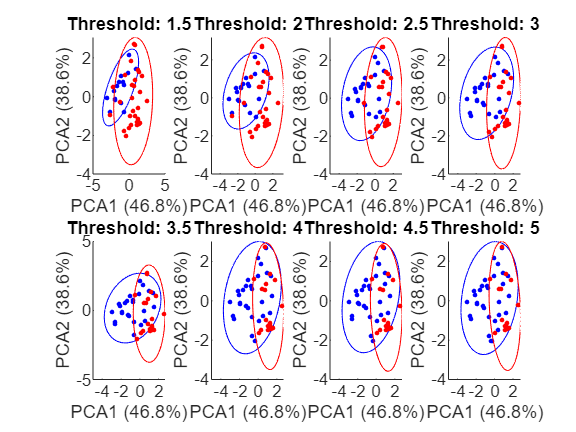

figure
panel=1;
PartSurge=[];
for k=1.5:0.5:5
    Surge=Comb.Casos>=k;
    subplot(2,4,panel)
    [grp, grpID] = findgroups(Surge);
    clrMap = redblue(numel(grpID));
    grpID=double(grpID)+1;
    for i = 1:max(grpID)
        ScoreGroup = score(grp==i, 1:2);
        covarianceMatrix = cov(ScoreGroup);
        [eigenvectors, eigenvalues] = eig(covarianceMatrix);
        theta = linspace(0, 2*pi, 100);
        ellipseRadius = 2.4477 * sqrt(diag(eigenvalues)); % 95% confidence corresponds to 2.4477 std dev
        % Step 6: Parametrize the ellipse
        ellipseX = ellipseRadius(1) * cos(theta);
        ellipseY = ellipseRadius(2) * sin(theta);
        % Step 7: Rotate and translate the ellipse into PCA space
        ellipsePoints = [ellipseX; ellipseY];
        ellipsePointsRotated = eigenvectors * ellipsePoints;
        scatter(ScoreGroup(:, 1), ScoreGroup(:, 2), 5, clrMap(i,:), 'filled','o');  % Scatter plot of points
        hold on;
        % Step 9: Plot the confidence ellipse
        plot(ellipsePointsRotated(1, :) + mean(ScoreGroup(:, 1)), ...
        ellipsePointsRotated(2, :) + mean(ScoreGroup(:, 2)),'-', 'LineWidth', 0.5,'Color',clrMap(i,:));
    end
    title("Threshold: "+k)
    xlabel("PCA1 ("+round(exp(1),1)+"%)")
    ylabel("PCA2 ("+round(exp(2),1)+"%)")
    panel=panel+1;
    hold off
    PartSurge=[PartSurge; k nnz(Surge) numel(Surge)-nnz(Surge)];
end

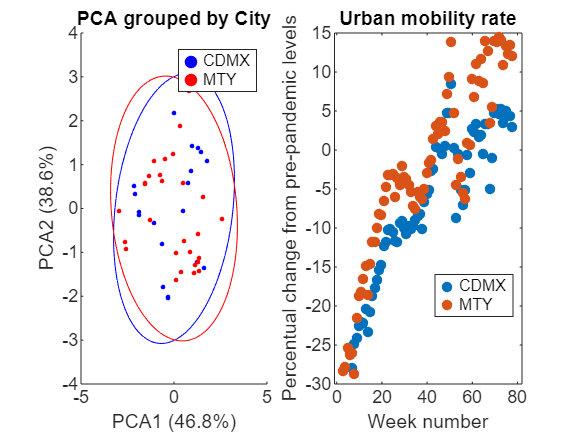

figure
subplot(1,2,1)
[grp, grpID] = findgroups(Comb.Ciudad);
clrMap = redblue(numel(grpID));
grpID=double(grpID)+1;
for i = 1:2
    ScoreCity = score(grp==i, 1:2);
    covarianceMatrix = cov(ScoreCity);
    [eigenvectors, eigenvalues] = eig(covarianceMatrix);
    theta = linspace(0, 2*pi, 100);
    ellipseRadius = 2.4477 * sqrt(diag(eigenvalues)); % 95% confidence corresponds to 2.4477 std dev
        % Step 6: Parametrize the ellipse
    ellipseX = ellipseRadius(1) * cos(theta);
    ellipseY = ellipseRadius(2) * sin(theta);
        % Step 7: Rotate and translate the ellipse into PCA space
    ellipsePoints = [ellipseX; ellipseY];
    ellipsePointsRotated = eigenvectors * ellipsePoints;
    scatter(ScoreCity(:, 1), ScoreCity(:, 2), 5, clrMap(i,:), 'filled','o');  % Scatter plot of points
    hold on;
        % Step 9: Plot the confidence ellipse
    plot(ellipsePointsRotated(1, :) + mean(ScoreCity(:, 1)), ...
    ellipsePointsRotated(2, :) + mean(ScoreCity(:, 2)),'-', 'LineWidth', 0.5,'Color',clrMap(i,:),'HandleVisibility','off');
end
hold off
title("PCA grouped by City")
xlabel("PCA1 ("+round(exp(1),1)+"%)")
ylabel("PCA2 ("+round(exp(2),1)+"%)")
legend("CDMX","MTY")
subplot(1,2,2)
gscatter(MTY_CDMX_Combinado.Semana,MTY_CDMX_Combinado.AVG_Mobility,MTY_CDMX_Combinado.Ciudad)
title("Urban mobility rate")
xlabel("Week number")
ylabel("Percentual change from pre-pandemic levels")

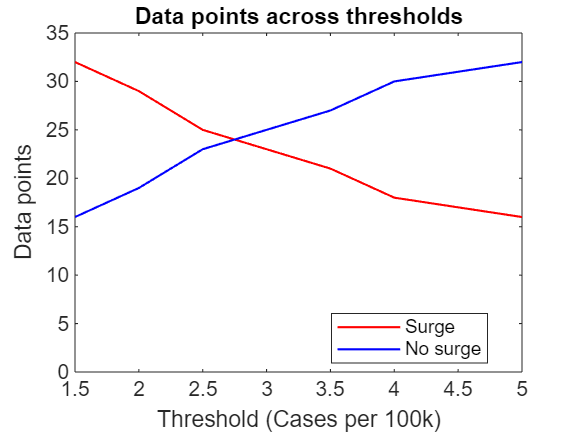

figure
plot(PartSurge(:,1),PartSurge(:,2),"Color","r","LineWidth",1);
hold on
plot(PartSurge(:,1),PartSurge(:,3),"Color","b","LineWidth",1);
hold off
title("Data points across thresholds")
xlabel("Threshold (Cases per 100k)")
ylabel("Data points")
ylim([0,35])
xlim([1.5,5])
legend(["Surge","No surge"],Location="best")

Cluster_Acc=[];
for i=1:0.5:4
    Threshold=i;
    Grupo_Real=Comb.Casos>=Threshold;
    Z = linkage(table2array(Comb(:,4:end-1)), "average","euclidean"); %From the experiment Manager
    numClusters = 2;
    idx = cluster(Z, 'maxclust', numClusters);
    Result=[Grupo_Real idx];
    if nnz(idx==1)>nnz(idx==2)
        Cluster_Mayor=Result(Result(:,2)==1,1);
        Cluster_Menor=Result(Result(:,2)==2,1);
        if nnz(Cluster_Mayor==1)>nnz(Cluster_Menor==0)
            Dir_CMayor=1;
            Dir_CMenor=0;
            Acc_CMayor=nnz(Cluster_Mayor==Dir_CMayor)./numel(Cluster_Mayor);
            Acc_CMenor=nnz(Cluster_Menor==Dir_CMenor)./numel(Cluster_Menor);
        else
            Dir_CMayor=0;
            Dir_CMenor=1;
            Acc_CMayor=nnz(Cluster_Mayor==Dir_CMayor)./numel(Cluster_Mayor);
            Acc_CMenor=nnz(Cluster_Menor==Dir_CMenor)./numel(Cluster_Menor);
        end
    else
        Cluster_Mayor=Result(Result(:,2)==2,1);
        Cluster_Menor=Result(Result(:,2)==1,1);
        if nnz(Cluster_Mayor==1)>nnz(Cluster_Menor==0)
            Dir_CMayor=1;
            Dir_CMenor=0;
            Acc_CMayor=nnz(Cluster_Mayor==Dir_CMayor)./numel(Cluster_Mayor);
            Acc_CMenor=nnz(Cluster_Menor==Dir_CMenor)./numel(Cluster_Menor);
        else
            Dir_CMayor=0;
            Dir_CMenor=1;
            Acc_CMayor=nnz(Cluster_Mayor==Dir_CMayor)./numel(Cluster_Mayor);
            Acc_CMenor=nnz(Cluster_Menor==Dir_CMenor)./numel(Cluster_Menor);
        end
    end
    Acc_Matrix=[Acc_CMayor numel(Cluster_Mayor); Acc_CMenor numel(Cluster_Menor)];
    Acc_Total=sum(Acc_Matrix(:,1).*Acc_Matrix(:,2))/sum(Acc_Matrix(:,2));
    Cluster_Acc=[Cluster_Acc; i Acc_Total];
end
Cluster_Acc=array2table(Cluster_Acc,"VariableNames",["Threshold","Accuracy"])

Cluster_Acc = 7x2 table
    Threshold    Accuracy
    _________    ________

         1       0.77083 
       1.5       0.85417 
         2       0.83333 
       2.5       0.79167 
         3       0.79167 
       3.5          0.75 
         4        0.6875 


Threshold=Cluster_Acc{Cluster_Acc.Accuracy==max(Cluster_Acc.Accuracy),"Threshold"}

Threshold = 1.5000

Comb.F0=Comb.Casos>=Threshold

Comb = 48x9 table
    Ciudad    Poblacion     Semana    Max_Campus    WBE_Dato    x_EdPositivos    AVG_Mobility     Casos      F0  
    ______    __________    ______    __________    ________    _____________    ____________    _______    _____

     MTY      5.3221e+06      32        0.38414      0.65378      -0.03314          -1.1499       23.699    true 
     MTY      5.3221e+06      34        0.64652      0.86027       0.13655          -1.4827        24.44    true 
     MTY      5.3221e+06      35        0.31634        1.018       0.30675          -1.5247       20.153    true 
     MTY      5.3221e+06      36        0.22201       1.3279      -0.20283          -1.2489        15.73 

Group=string(double(Comb.Casos>=Threshold))

Group = 48x1 string array
    "1"
    "1"
    "1"
    "1"
    "1"
    "1"
    "1"
    "1"
    "1"
    "1"
    "1"
    "1"
    "1"
    "1"
    "1"
    "0"
    "0"
    "0"
    "0"
    "0"
    "0"
    "0"
    "0"
    "0"
    "1"
    "1"
    "1"
    "1"
    "1"
    "1"


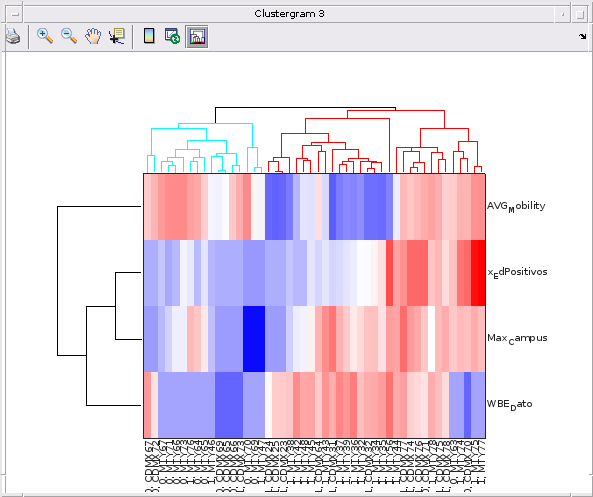

columnLabels = strcat(Group,", ",string(Comb.Ciudad),string(Comb.Semana));
rowLabels = Comb.Properties.VariableNames(4:end-2); % Feature names

cg = clustergram(table2array(Comb(:,4:end-2))', ...
  'RowLabels', rowLabels, ...
  'ColumnLabels', columnLabels, ...
  'RowPDist', 'correlation', ....
  'ColumnPDist', 'euclidean', ...
  'Linkage', 'average', ...
  'Colormap',redblue(), ...
  'Dendrogram',3);

%{
iter=1;
Training={};
while iter<51
Tra_set=randsample([1:1:47],33,false)';
Tes_set=~ismember([1:1:47]',Tra_set);
Comb_Tra=Comb(Tra_set,["Max_Campus","WBE_Dato","x_EdPositivos","AVG_Mobility","F0"]);
Comb_Tes=Comb(Tes_set,["Max_Campus","WBE_Dato","x_EdPositivos","AVG_Mobility","F0"]);
WBE_Class=fitcauto(Comb_Tra,"F0","Learners","all-linear","HyperparameterOptimizationOptions",struct("MaxObjectiveEvaluations",50,"Verbose",0,"ShowPlots",false));
Tra_PC=predict(WBE_Class,Comb_Tra);
Tra_CC=confusionmat(Comb_Tra.F0,Tra_PC);
Tra_TP=Tra_CC(2,2);
Tra_FP=Tra_CC(1,2);
Tra_TN=Tra_CC(1,1);
Tra_FN=Tra_CC(2,1);
Tra_Acc=(Tra_TP+Tra_TN)/sum(Tra_CC,"all");
Tra_Sp=Tra_TN/(Tra_TN+Tra_FP);
Tra_Sn=Tra_TP/(Tra_TP+Tra_FN);
Tra_J=Tra_Sp+Tra_Sn-1;
Tes_PC=predict(WBE_Class,Comb_Tes);
Tes_CC=confusionmat(Comb_Tes.F0,Tes_PC);
Tes_TP=Tes_CC(2,2);
Tes_FP=Tes_CC(1,2);
Tes_TN=Tes_CC(1,1);
Tes_FN=Tes_CC(2,1);
Tes_Acc=(Tes_TP+Tes_TN)/sum(Tes_CC,"all");
Tes_Sp=Tes_TN/(Tes_TN+Tes_FP);
Tes_Sn=Tes_TP/(Tes_TP+Tes_FN);
Tes_J=Tes_Sp+Tes_Sn-1;
Training(iter,:)={iter Comb Tra_set Tes_set WBE_Class Tra_Acc Tes_Acc Tra_J Tes_J};
iter=iter+1
end

performance=array2table(Training(:,[1 6:9]),"VariableNames",["iter","Tra_Acc","Tes_Acc","Tra_J","Tes_J"])
writetable(performance,"Clas_Training_13DIC.csv")

Best_Model=Training(7,:);
Clas_Model=struct("Full_Data",Best_Model(:,2),"IdxTrain",Best_Model(:,3), "IdxTest",Best_Model(:,4),"Model",Best_Model(:,5))
save("Clas_Model_13DIC.mat","Clas_Model",'-mat')
%}

load("Clas_Model_13DIC.mat")
Comb_Tra=Clas_Model.Full_Data(Clas_Model.IdxTrain,["Max_Campus","WBE_Dato","x_EdPositivos","AVG_Mobility","F0"]);
Comb_Tes=Clas_Model.Full_Data(Clas_Model.IdxTest,["Max_Campus","WBE_Dato","x_EdPositivos","AVG_Mobility","F0"]);
Tra_PC=predict(Clas_Model.Model,Comb_Tra);
Tra_CC=confusionmat(Comb_Tra.F0,Tra_PC)

Tra_CC =     12     1
     3    17


Tra_TP=Tra_CC(2,2);
Tra_FP=Tra_CC(1,2);
Tra_TN=Tra_CC(1,1);
Tra_FN=Tra_CC(2,1);
Tra_Acc=(Tra_TP+Tra_TN)/sum(Tra_CC,"all");
Tra_Sp=Tra_TN/(Tra_TN+Tra_FP);
Tra_Sn=Tra_TP/(Tra_TP+Tra_FN);
Tra_J=Tra_Sp+Tra_Sn-1;
Tes_PC=predict(Clas_Model.Model,Comb_Tes);
Tes_CC=confusionmat(Comb_Tes.F0,Tes_PC)

Tes_CC =      2     1
     1    10


Tes_TP=Tes_CC(2,2);
Tes_FP=Tes_CC(1,2);
Tes_TN=Tes_CC(1,1);
Tes_FN=Tes_CC(2,1);
Tes_Acc=(Tes_TP+Tes_TN)/sum(Tes_CC,"all");
Tes_Sp=Tes_TN/(Tes_TN+Tes_FP);
Tes_Sn=Tes_TP/(Tes_TP+Tes_FN);
Tes_J=Tes_Sp+Tes_Sn-1;
Class_Metrics=array2table([Tra_Acc Tra_Sn Tra_Sp Tra_J; Tes_Acc Tes_Sn Tes_Sp Tes_J],"VariableNames",["Accuracy","Sensitivity","Specificity","Youden"],"RowNames",["Training","Test"])

Class_Metrics = 2x4 table
                Accuracy    Sensitivity    Specificity    Youden 
                ________    ___________    ___________    _______

    Training    0.87879          0.85        0.92308      0.77308
    Test        0.85714       0.90909        0.66667      0.57576


Case_Data=MTY_CDMX_Combinado(:,["Ciudad","Semana","Casos"]);
F1=[];
F1C=[];
F2=[];
F2C=[];
for k=1:1:height(Comb)
    if Comb.Semana(k)+1<=max(Case_Data.Semana)
        Fk1=Case_Data{and(Case_Data.Semana==Comb.Semana(k)+1,Case_Data.Ciudad==Comb.Ciudad(k)),"Casos"}>=Threshold;
        F1=[F1; Comb.Semana(k) Fk1];
        F1C=[F1C; Comb.Ciudad(k)];
    end
    if Comb.Semana(k)+2<=max(Case_Data.Semana)
        Fk2=Case_Data{and(Case_Data.Semana==Comb.Semana(k)+2,Case_Data.Ciudad==Comb.Ciudad(k)),"Casos"}>=Threshold;
        F2=[F2; Comb.Semana(k) Fk2];
        F2C=[F2C; Comb.Ciudad(k)];
    end
end
F1=array2table(F1,"VariableNames",["Semana","F1"]);
F1.Ciudad=F1C;
F2=array2table(F2,"VariableNames",["Semana","F2"]);
F2.Ciudad=F2C;

F1_Class=[];
F2_Class=[];
for i=1:1:height(F1)
    F1_Class=[F1_Class; Comb(and(Comb.Ciudad==F1.Ciudad(i),Comb.Semana==F1.Semana(i)),["Max_Campus","WBE_Dato","x_EdPositivos","AVG_Mobility"]) F1(i,"F1")];
end
for i=1:1:height(F2)
    F2_Class=[F2_Class; Comb(and(Comb.Ciudad==F2.Ciudad(i),Comb.Semana==F2.Semana(i)),["Max_Campus","WBE_Dato","x_EdPositivos","AVG_Mobility"]) F2(i,"F2")];
end
F1_Class

F1_Class = 46x5 table
    Max_Campus    WBE_Dato    x_EdPositivos    AVG_Mobility    F1
    __________    ________    _____________    ____________    __

      0.38414      0.65378      -0.03314          -1.1499      1 
      0.64652      0.86027       0.13655          -1.4827      1 
      0.31634        1.018       0.30675          -1.5247      1 
      0.22201       1.3279      -0.20283          -1.2489      1 
      0.80925       1.2388      -0.37303          -1.3328      1 
     -0.49227       0.5988      -0.57431          -1.3658      1 
      0.53803       1.0749      -0.28029          -1.2009      1 
     -0.18552        1.179      -0.73381          -0.7361      1 
        1.152       1.0989      -0.28029         -0.40326      1 
      0.93586      0.87412       0.95493         -0.19336      1 
      0.15361  

F2_Class

F2_Class = 44x5 table
    Max_Campus    WBE_Dato    x_EdPositivos    AVG_Mobility    F2
    __________    ________    _____________    ____________    __

      0.38414      0.65378      -0.03314          -1.1499      1 
      0.64652      0.86027       0.13655          -1.4827      1 
      0.31634        1.018       0.30675          -1.5247      1 
      0.22201       1.3279      -0.20283          -1.2489      1 
      0.80925       1.2388      -0.37303          -1.3328      1 
     -0.49227       0.5988      -0.57431          -1.3658      1 
      0.53803       1.0749      -0.28029          -1.2009      1 
     -0.18552        1.179      -0.73381          -0.7361      1 
        1.152       1.0989      -0.28029         -0.40326      1 
      0.93586      0.87412       0.95493         -0.19336      1 
      0.15361  

F1_PC=predict(Clas_Model.Model,F1_Class(:,1:end-1));
F1_CC=confusionmat(logical(F1_Class.F1),F1_PC)

F1_CC =     12     3
     6    25


F1_TP=F1_CC(2,2);
F1_FP=F1_CC(1,2);
F1_TN=F1_CC(1,1);
F1_FN=F1_CC(2,1);
F1_Acc=(F1_TP+F1_TN)/sum(F1_CC,"all");
F1_Sp=F1_TN/(F1_TN+F1_FP);
F1_Sn=F1_TP/(F1_TP+F1_FN);
F1_J=F1_Sp+F1_Sn-1;
F2_PC=predict(Clas_Model.Model,F2_Class(:,1:end-1));
F2_CC=confusionmat(logical(F2_Class.F2),F2_PC)

F2_CC =     12     2
     6    24


F2_TP=F2_CC(2,2);
F2_FP=F2_CC(1,2);
F2_TN=F2_CC(1,1);
F2_FN=F2_CC(2,1);
F2_Acc=(F2_TP+F2_TN)/sum(F2_CC,"all");
F2_Sp=F2_TN/(F2_TN+F2_FP);
F2_Sn=F2_TP/(F2_TP+F2_FN);
F2_J=F2_Sp+F2_Sn-1;
ClassF_Metrics=array2table([F1_Acc F1_Sn F1_Sp F1_J; F2_Acc F2_Sn F2_Sp F2_J],"VariableNames",["Accuracy","Sensitivity","Specificity","Youden"],"RowNames",["F1","F2"])

ClassF_Metrics = 2x4 table
          Accuracy    Sensitivity    Specificity    Youden 
          ________    ___________    ___________    _______

    F1    0.80435       0.80645            0.8      0.60645
    F2    0.81818           0.8        0.85714      0.65714


Class_Metrics=[Class_Metrics; ClassF_Metrics]

Class_Metrics = 4x4 table
                Accuracy    Sensitivity    Specificity    Youden 
                ________    ___________    ___________    _______

    Training    0.87879          0.85        0.92308      0.77308
    Test        0.85714       0.90909        0.66667      0.57576
    F1          0.80435       0.80645            0.8      0.60645
    F2          0.81818           0.8        0.85714      0.65714


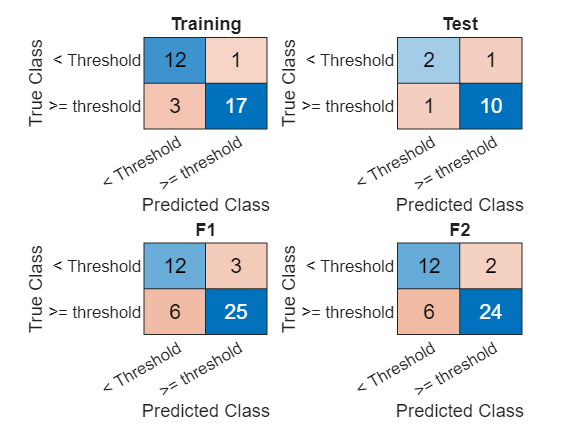

CCs={Tra_CC Tes_CC F1_CC F2_CC; "Training" "Test" "F1" "F2"};
figure
for i=1:numel(CCs(1,:))
    subplot(2,2,i)
    confusionchart(CCs{1,i},["< Threshold",">= threshold"]);
    title(CCs{2,i})
end

%Linear_FIT=fitlm(table2array(Comb(:,["Max_Campus","WBE_Dato","x_EdPositivos","AVG_Mobility"])),table2array(Comb(:,8)))
%Linear_FIT=fitlm(table2array(Comb(:,["WBE_Dato","x_EdPositivos","AVG_Mobility"])),table2array(Comb(:,8)))
Linear_FIT=fitlm(table2array(Comb(:,["x_EdPositivos","AVG_Mobility"])),table2array(Comb(:,8)))

Linear_FIT = Linear regression model:
    y ~ 1 + x1 + x2

Estimated Coefficients:
                   Estimate      SE       tStat       pValue  
                   ________    ______    _______    __________

    (Intercept)     7.4763     1.4467      5.168    5.2472e-06
    x1              5.9171     1.5225     3.8864    0.00033155
    x2             -7.1326     1.5225    -4.6848    2.6071e-05


Number of observations: 48, Error degrees of freedom: 45
Root Mean Squared Error: 10
R-squared: 0.4,  Adjusted R-Squared: 0.374
F-statistic vs. constant model: 15, p-value = 1.01e-05

figure
LinFit_Performance=[Linear_FIT.RMSE Linear_FIT.Rsquared.Ordinary mape(Linear_FIT.Fitted,table2array(Comb(:,8)))]

LinFit_Performance =    10.0227    0.4002  398.7772


%{
Modelos_Reg={};
Iter=1
while Iter<=50
Tra_set=randsample([1:1:height(Comb)],33,false)';
Tes_set=~ismember([1:1:height(Comb)]',Tra_set);
Comb_Tra=Comb(Tra_set,["Max_Campus","WBE_Dato","x_EdPositivos","AVG_Mobility","Casos"]);
Comb_Tes=Comb(Tes_set,["Max_Campus","WBE_Dato","x_EdPositivos","AVG_Mobility","Casos"]);
WBS_Reg=fitrauto(Comb_Tra,"Casos","Learners","all","HyperparameterOptimizationOptions",struct("MaxObjectiveEvaluations",30,"Verbose",0,"ShowPlots",false));
Tra_Pred=predict(WBS_Reg,Comb_Tra);
Tra_RMSE=rmse(Tra_Pred,Comb_Tra.Casos);
Tra_Mdl=fitlm(Comb_Tra.Casos,Tra_Pred);
Tra_R2=Tra_Mdl.Rsquared.Ordinary;
Tra_MAPE=mape(Tra_Pred,Comb_Tra.Casos);
Tes_Pred=predict(WBS_Reg,Comb_Tes);
Tes_RMSE=rmse(Tes_Pred,Comb_Tes.Casos);
Tes_Mdl=fitlm(Comb_Tes.Casos,Tes_Pred);
Tes_R2=Tes_Mdl.Rsquared.Ordinary;
Tes_MAPE=mape(Tes_Pred,Comb_Tes.Casos);
Modelos_Reg(Iter,:)={Iter Comb Tra_set Tes_set WBS_Reg Tra_RMSE Tra_R2 Tra_MAPE Tes_RMSE Tes_R2 Tes_MAPE};
Iter=Iter+1
end

Performance=array2table(Modelos_Reg(:,[1 6:end]),"VariableNames",["Iter","Tr_RMSE","Tr_R2","Tr_MAPE","Te_RMSE","Te_R2","Te_MAPE"])
writetable(Performance,"Class_Training_13DIC.csv");

Best_Reg=Modelos_Reg(43,:);
Reg_Model=struct("Full_Data",Best_Reg{:,2},"IdxTrain",Best_Reg{:,3}, "IdxTest",Best_Reg{:,4},"Model",Best_Reg{:,5})
save("Reg_Model_13DIC.mat","Reg_Model",'-mat')
%}

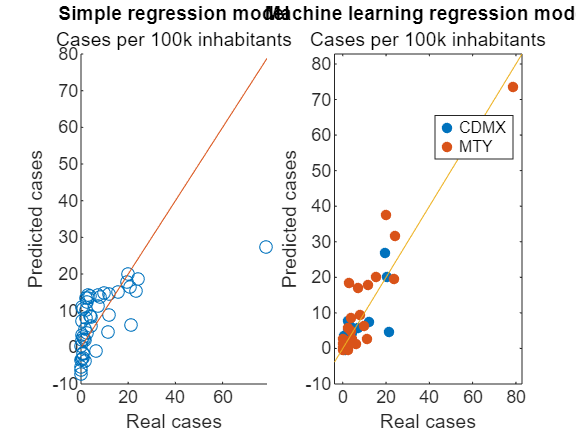

figure
subplot(1,2,1)
scatter(table2array(Comb(:,8)),Linear_FIT.Fitted)
xrange=linspace(table2array(min(Comb(:,8))),table2array(max(Comb(:,8))),10);
yrange=xrange;
hold on
plot(xrange,yrange)
title("Simple regression model")
subtitle("Cases per 100k inhabitants")
xlabel("Real cases")
ylabel("Predicted cases")
hold off

subplot(1,2,2)
load("Reg_Model_13DIC.mat")
Real_Casos=Reg_Model.Full_Data.Casos;
Pred_Casos=predict(Reg_Model.Model,Reg_Model.Full_Data(:,["Max_Campus","WBE_Dato","x_EdPositivos","AVG_Mobility","Casos"]));
gscatter(Real_Casos,Pred_Casos,Reg_Model.Full_Data.Ciudad)
hold on
A2=refline(1,0);
A2.HandleVisibility="off";
hold off
title("Machine learning regression model");
subtitle("Cases per 100k inhabitants")
ylabel("Predicted cases")
xlabel("Real cases")

rmse(Pred_Casos,Real_Casos)

ans = 5.4330

mape(Pred_Casos,Real_Casos)

ans = 133.9380

model_pred=fitlm(Real_Casos,Pred_Casos);
model_pred.Rsquared.Ordinary

ans = 0.8316